## Efficient determination of the transfer function of a mechanical system, and its use in determining the H2 norm of a system

First, we create the graph of the mechanical network representing the one-wheeled train suspension system - refer to section IV of the associated paper. Note that credit is given to Matthias Hotz for his suite of functions for finding all spanning trees of a simple, undirected graph.

Matthias Hotz (2023). generateSpanningTrees(A) (https://www.mathworks.com/matlabcentral/fileexchange/53787-generatespanningtrees-a), MATLAB Central File Exchange. Retrieved October 9, 2023.

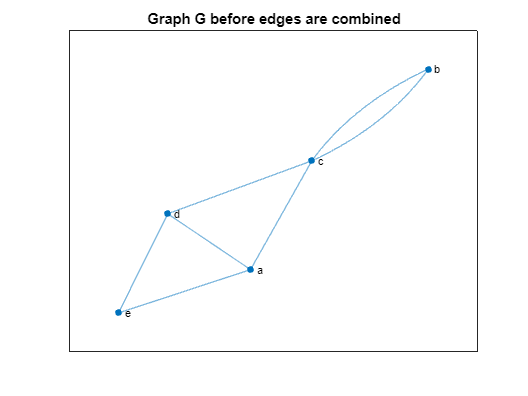

%%%%%%%%%%%%%%%%%% TRAIN SUSPENSION GRAPH %%%%%%%%%%%%%%%%%%%%%%%%%%%
close all; clear all; clc
%% Create graph
syms s mw ms mb kw cw x1 x2 kb ks
% source and destination nodes
src = [1 1 2 2 3 4 1];
dst = [3 4 3 3 4 5 5];
% Define symbolic weights
Q1 = (ks/s) + x1;
Q2 = (kb/s) + x2;
weights_symbolic = [mw*s, mb*s, cw, kw/s, Q2, Q1, ms*s];
names = {'a' 'b' 'c' 'd' 'e'};
% Dummy variable of weights created as MATLAB requires weights for an
% adjacency matrix to be made
weights = [1, 1, 1, 1, 1, 1, 1];
% Create graph and plot
G = graph(src,dst,weights,names);
figure(1)
plot(G)
title("Graph G before edges are combined")

Once the graph has been made, any repeated edges are summed.

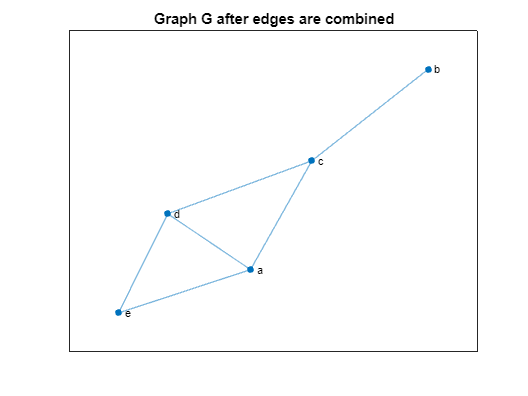

%% Combine repeated edges
[src, dst, weights_symbolic_original] = combine_edge(src, dst, weights_symbolic);
G_combined_edges = graph(src,dst,weights(1:6),names);
figure(2)
plot(G_combined_edges)
title("Graph G after edges are combined")

Then, following the formulae in section IV, the relevant tree admittance products are found by combining vertices on the graph G. Note that, when vertices are combined, we must ensure that there are no repeated edges again.

%% Combine vertices a and e, find admittance product
[tempsrc, tempdst, weights_symbolic] = combine_vertices(src, dst, weights_symbolic_original, 5,1);

%% Combine repeated edges
[tempsrc, tempdst, weights_symbolic] = combine_edge(tempsrc, tempdst, weights_symbolic);

Finally, all spanning trees for this graph are found by creating a new graph and using the aforementioned functions. These spanning trees are shown in the paper, visualising what this code is doing. The admittance products of these spanning trees are then summed.

%% Finding number of spanning trees
weights = ones(1,length(weights_symbolic));
names = {'a' 'b' 'c' 'd'};
G = graph(tempsrc,tempdst,weights,names);
A = adjacency(G);
% Store number of spanning trees
numSpanning = getNumberSpanningTrees(A);

% Find all spanning trees
[idx, src_spn, dst_spn] = generateSpanningTrees(A);
% Create empty vector to store the source and destination pairs for each
% spanning tree
answer = [];

for n = 1:size(idx, 2)      % Iterate through all spanning trees
% Store source and destination vertex of all edges of spanning tree n:
    answer = [answer;src_spn(idx(:, n)), dst_spn(idx(:, n))];
end

%% Compute the sum of products of each spanning tree
T_ae = sum_admittance_products(answer, numSpanning, tempsrc, tempdst, weights_symbolic);

This is then repeated for each vertex pair that needs to be combined. In this case, because we combine vertices b and a, we must subtract 1 from each index for the vertices as MATLAB assumes that vertices are numbered starting from 1 (which is equivalent to vertex a, which we have combined with vertex b).

%% Repeat for 2 -> 1
%% Combine vertices b and a, find admittance product
[tempsrc, tempdst, weights_symbolic] = combine_vertices(src, dst, weights_symbolic_original, 1, 2);

%% Combine repeated edges
[tempsrc, tempdst, weights_symbolic] = combine_edge(tempsrc, tempdst, weights_symbolic);
tempsrc = tempsrc - 1;
tempdst = tempdst - 1;

%% Finding number of spanning trees
weights = ones(1,length(weights_symbolic));
names = {'b' 'c' 'd' 'e'};
G = graph(tempsrc,tempdst,weights,names);
% Create adjacency matrix
A = adjacency(G);
% Store number of spanning trees
numSpanning = getNumberSpanningTrees(A);

% Find all spanning trees
[idx, src_spn, dst_spn] = generateSpanningTrees(A);
% Create empty vector to store the source and destination pairs for each
% spanning tree
answer = [];

for n = 1:size(idx, 2)      % Iterate through all spanning trees
% Store source and destination vertex of all edges of spanning tree n:
    answer = [answer;src_spn(idx(:, n)), dst_spn(idx(:, n))];
end

%% Compute the sum of products of each spanning tree
T_ba = sum_admittance_products(answer, numSpanning, tempsrc, tempdst, weights_symbolic);

And finally, we repeat for the vertex pair b and e.

%% Now repeat for T_(b,e)
%% Combine vertices b and e, find admittance product
[tempsrc, tempdst, weights_symbolic] = combine_vertices(src, dst, weights_symbolic_original, 5, 2);

%% Combine repeated edges
[tempsrc, tempdst, weights_symbolic] = combine_edge(tempsrc, tempdst, weights_symbolic);

%% Finding number of spanning trees
weights = ones(1,length(weights_symbolic));
names = {'a' 'b' 'c' 'd'};
G = graph(tempsrc,tempdst,weights,names);
% Create adjacency matrix
A = adjacency(G);
% Store number of spanning trees
numSpanning = getNumberSpanningTrees(A);

% Find all spanning trees
[idx, src_spn, dst_spn] = generateSpanningTrees(A);
% Create empty vector to store the source and destination pairs for each
% spanning tree
answer = [];

for n = 1:size(idx, 2)      % Iterate through all spanning trees
% Store source and destination vertex of all edges of spanning tree n:
    answer = [answer;src_spn(idx(:, n)), dst_spn(idx(:, n))];
end

%% Compute the sum of products of each spanning tree
% Currently only for spanning tree with 4 nodes, due to the symbolic
% weights - need to generalise this
T_be = sum_admittance_products(answer, numSpanning, tempsrc, tempdst, weights_symbolic);

Following the equations given in the paper, we compute the transfer function.

%% Combine for final answer
TF = (1/2 * (T_ae + T_ba - T_be) * s) / T_ba;
[n, d] = numden(TF)

$$n = s\,\left(\mathrm{kb}\,\mathrm{ks}\,\mathrm{kw}+\mathrm{cw}\,\mathrm{kb}\,\mathrm{ks}\,s+\mathrm{kb}\,\mathrm{kw}\,s\,x_{1}+\mathrm{ks}\,\mathrm{kw}\,s\,x_{2}+\mathrm{cw}\,\mathrm{kb}\,s^{2}\,x_{1}+\mathrm{cw}\,\mathrm{ks}\,s^{2}\,x_{2}+\mathrm{cw}\,s^{3}\,x_{1}\,x_{2}+\mathrm{kw}\,s^{2}\,x_{1}\,x_{2}\right)$$

$$d = \mathrm{kb}\,\mathrm{ks}\,\mathrm{kw}+\mathrm{cw}\,\mathrm{kb}\,\mathrm{ks}\,s+\mathrm{kb}\,\mathrm{kw}\,s\,x_{1}+\mathrm{ks}\,\mathrm{kw}\,s\,x_{2}+\mathrm{cw}\,\mathrm{kb}\,\mathrm{ms}\,s^{3}+\mathrm{cw}\,\mathrm{ks}\,\mathrm{mb}\,s^{3}+\mathrm{cw}\,\mathrm{ks}\,\mathrm{ms}\,s^{3}+\mathrm{cw}\,\mathrm{mb}\,\mathrm{ms}\,s^{5}+\mathrm{kb}\,\mathrm{ks}\,\mathrm{mb}\,s^{2}+\mathrm{kb}\,\mathrm{ks}\,\mathrm{ms}\,s^{2}+\mathrm{kb}\,\mathrm{ks}\,\mathrm{mw}\,s^{2}+\mathrm{kb}\,\mathrm{kw}\,\mathrm{ms}\,s^{2}+\mathrm{ks}\,\mathrm{kw}\,\mathrm{mb}\,s^{2}+\mathrm{ks}\,\mathrm{kw}\,\mathrm{ms}\,s^{2}+\mathrm{kb}\,\mathrm{mb}\,\mathrm{ms}\,s^{4}+\mathrm{kb}\,\mathrm{ms}\,\mathrm{mw}\,s^{4}+\mathrm{ks}\,\mathrm{mb}\,\mathrm{mw}\,s^{4}+\mathrm{kw}\,\mathrm{mb}\,\mathrm{ms}\,s^{4}+\mathrm{ks}\,\mathrm{ms}\,\mathrm{mw}\,s^{4}+\mathrm{cw}\,\mathrm{kb}\,s^{2}\,x_{1}+\mathrm{cw}\,\mathrm{ks}\,s^{2}\,x_{2}+\mathrm{mb}\,\mathrm{ms}\,\mathrm{mw}\,s^{6}+\mathrm{cw}\,\mathrm{mb}\,s^{4}\,x_{1}+\mathrm{cw}\,\mathrm{ms}\,s^{4}\,x_{1}+\mathrm{cw}\,\mathrm{ms}\,s^{4}\,x_{2}+\mathrm{kb}\,\mathrm{mb}\,s^{3}\,x_{1}+\mathrm{kb}\,\mathrm{ms}\,s^{3}\,x_{1}+\mathrm{ks}\,\mathrm{mb}\,s^{3}\,x_{2}+\mathrm{kb}\,\mathrm{mw}\,s^{3}\,x_{1}+\mathrm{kw}\,\mathrm{mb}\,s^{3}\,x_{1}+\mathrm{ks}\,\mathrm{ms}\,s^{3}\,x_{2}+\mathrm{kw}\,\mathrm{ms}\,s^{3}\,x_{1}+\mathrm{ks}\,\mathrm{mw}\,s^{3}\,x_{2}+\mathrm{kw}\,\mathrm{ms}\,s^{3}\,x_{2}+\mathrm{mb}\,\mathrm{ms}\,s^{5}\,x_{2}+\mathrm{mb}\,\mathrm{mw}\,s^{5}\,x_{1}+\mathrm{ms}\,\mathrm{mw}\,s^{5}\,x_{1}+\mathrm{ms}\,\mathrm{mw}\,s^{5}\,x_{2}+\mathrm{cw}\,s^{3}\,x_{1}\,x_{2}+\mathrm{kw}\,s^{2}\,x_{1}\,x_{2}+\mathrm{mb}\,s^{4}\,x_{1}\,x_{2}+\mathrm{ms}\,s^{4}\,x_{1}\,x_{2}+\mathrm{mw}\,s^{4}\,x_{1}\,x_{2}$$

### Computing the H2 norm from the symbolic transfer function

Now that we have computed the symbolic transfer function, we can begin to calculate the H2 norm using the method outlined in reference 3 of the associated paper to this script. We begin by defining suspension admittances that we will later optimise over.

syms ms mb mw ks kb kw cw z s cb cs x y t;
syms x1  x2 real
x = [x1;x2]; % these will be suspension admittances that we optimise over to minimise the H2 norm
% Parameters for K1 and K2
K1 = x1;
K2 = x2;
% Suspension admittances
Q1 = (ks/s) + K1;
Q2 = (kb/s) + K2;
% State space representation of the system - no longer needed!
% A2 = [ms*s^2+Q1*s, -s*Q1, 0; -s*Q1, s^2*mb+s*(Q1+Q2), -s*Q2; 0, -s*Q2, mw*s^2+Q2*s+cw*s+kw];
% B2 = [0; 0; cw*s+kw];
% % Extract transfer function
% TFT = [s, 0, 0]*inv(A2)*B2;
% TFTF = TFT(1,1);
% toc
% [n, d] = numden(TFTF);

We substitute known values for the admittances of mechanical components, leaving only x1 and x2 as our optimisation variables. The H2 norm is then calculated (all functions are at the end of the script).

%% Evaluate symbolic TF so they're functions of x and y
ms = 3500; mb = 250; mw = 350; ks = 141E3; kb = 1260E3; cb = 7100; kw = 8E9; cw = 670E3; z = 200; cs = 8870;

% Extract numerator and denominator
cd = coeffs(subs(d),s, 'All');
cn = coeffs(subs(n),s,'All');
cn = [zeros(1, length(cd) - length(cn) - 1) cn];
% Flag to run symbolic version of functions
symbolic = 1;
% Create initial p polynomials
[n, pi, pi1] = H2norm_p_creation(cd);
% Create z_0
z0 = H2norm_z0_creation(cn,n,symbolic);
% Create initial variables for recursive method
[psi, epsilon, mu, gamma] = H2norm_intermediate_variables(pi, pi1, z0);
% First iteration of method - captures certain edge cases
[pi, pi1, z, mu, epsilon, psi, gamma] = H2norm_first_iteration(pi, pi1, z0, mu, epsilon, psi, gamma, n);
% Rest of iterations
[pi, pi1, z, mu, epsilon, psi, gamma] = H2norm_iterations(pi, pi1, z, mu, epsilon, psi, gamma, n);
%% Calculate H2 norm
H2 = z/(2*cd(1)*pi1)

We now have a symbolic expression for the H2 norm. The Jacobian and Hessian of this expression can be found and passed to an unconstrained minimisation optimisation algorithm, to minimise the H2 norm and therefore find the optimal suspension admittances, given by the variable xfinal.

%% Optimisation over x1 and x2 to minimise the H2 norm
gradf = jacobian(H2, [x]); % column gradf
hessf = jacobian(gradf); % column hessian
fh = matlabFunction(H2,gradf,hessf,'vars',{x});
options = optimoptions('fminunc', ...
    'SpecifyObjectiveGradient', true, ...
    'HessianFcn', 'objective', ...
    'Algorithm','trust-region', ...
    'Display','final');
[xfinal,fval,exitflag,output] = fminunc(fh,[10; 11],options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xfinal = 1.0e+04 *

    0.7616
    1.1844


fval = 620.8981

exitflag = 1

output = struct with fields:
         iterations: 20
          funcCount: 21
           stepsize: 1.7800
       cgiterations: 20
      firstorderopt: 7.1897e-09
          algorithm: 'trust-region'
            message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 7.189742e-09, ↵is less than options.OptimalityTolerance = 1.000000e-06, and no negative/zero↵curvature is detected in the trust-region model.'
    constrviolation: []


% xfinal has the values of x1 and x2 that minimise the H2 norm - agrees
% with paper
xfinal

xfinal = 1.0e+04 *

    0.7616
    1.1844


### Functions used in this livescript

function[n, pi, pi1] = H2norm_p_creation(cd)
    % Degree of transfer function = length of denominator - 1 (due to the
    % constant term)
    n = size(cd,2)-1;
    
    if mod(n,2) == 1
        % ODD
        pi1 = cd(2:2:end);
        pi = [cd(1:2:end) 0];
    else
        % EVEN
        pi = cd(1:2:end);
        pi1 = [cd(2:2:end) 0];
    end
end

function[z0] = H2norm_z0_creation(cn,n,symbolic)
    if symbolic
        syms t
        if mod(n,2) == 1
            % ODD
            % Define co and ce as the odd and even parts of the numerator polynomial,
            % respectively
            co = cn(2:2:end);
            ce = cn(1:2:end);
        
            % Square these polynomials, and add zeros to start and end of co2
            co2 = poly2sym(co,t)*poly2sym(co,t)*t;
            ce2 = poly2sym(ce,t)*poly2sym(ce,t);
            co2 = fliplr(coeffs(co2, t, 'All'));
            ce2 = fliplr(coeffs(ce2, t, 'All'));
            co2 = [0 co2 0];
        
            % Preallocate memory for z, change name of b to z0 (unnecessary)
            z0 = ce2 - co2;
        else
            % EVEN
            % Define co and ce as the odd and even parts of the numerator polynomial,
            % respectively
            % ce and co are the other way around in Tim's example?
            co = cn(1:2:end);
            ce = cn(2:2:end);
        
            % Square these polynomials, and add zeros to start and end of co2
            co2 = poly2sym(co,t)*poly2sym(co,t);
            ce2 = poly2sym(ce,t)*poly2sym(ce,t);
            co2 = coeffs(co2, t, 'All');
            ce2 = coeffs(ce2, t,'All');
        
            % CHECK NUMBER OF 0s
            %co2 = [0 co2 0];
        
            co2s = [co2, 0];
            %ce2 = [ce2, 0, 0];
            %co2s = co2;
            ns = size(co2s,2);
            for i = ns+1:n
                co2s = [0,co2s];
            end
            ns = size(ce2,2);
            for i = ns+1:n
                ce2 = [0,ce2];
            end
        
            % Preallocate memory for z0
            z0 = ce2 - co2s;
        end
    else
        if mod(n,2) == 1
            % ODD
            % Define co and ce as the odd and even parts of the numerator polynomial,
            % respectively
            co = cn(2:2:end);
            ce = cn(1:2:end);
        
            % Square these polynomials, and add zeros to start and end of co2
            co2 = conv(co, co);
            ce2 = conv(ce, ce);
            co2 = [0 co2 0];
        
            % Preallocate memory for b, which will be populated with the coefficients
            % of z_0
            b = zeros(1,length(cn));
        
            % Populates b with values of z_0
            for i = 1:length(cn)
                b(i) = ce2(i) - co2(i);
            end
        
            % Preallocate memory for z, change name of b to z0 (unnecessary)
            z0 = b;
        else
            % EVEN
            % Define co and ce as the odd and even parts of the numerator polynomial,
            % respectively
            ce = cn(2:2:end);
            co = cn(1:2:end);
        
            % Square these polynomials, and add zeros to start and end of co2
            co2 = conv(co, co);
            ce2 = conv(ce, ce);
            %co2 = [0 co2 0];
        
            co2s = [co2, 0];
            ns = size(co2s,2);
            for i = ns+1:n
                co2s = [0,co2s];
            end
            ns = size(ce2,2);
            for i = ns+1:n
                ce2 = [0,ce2];
            end
        
            % Preallocate memory for b, which will be populated with the coefficients
            % of z_0
            b = zeros(1,length(cn));
        
            % Populates b with values of z_0
            for i = 1:length(cn)
                b(i) = ce2(i) - co2s(i);
            end
        
            % Preallocate memory for z, change name of b to z0 (unnecessary)
            z0 = b;
        end
    end
end

function[psi, epsilon, mu, gamma] = H2norm_intermediate_variables(pi, pi1, z0)
    %% Variable definitions
    psi = pi(1);
    
    epsilon = z0(1);
    
    mu = pi1(1);
    
    gamma = pi(1);
end

function[pi, pi1, z, mu, epsilon, psi, gamma] = H2norm_first_iteration(pi, pi1, z0, mu, epsilon, psi, gamma, n)
    spi = [pi zeros(1, floor((n-1-1)/2))];
    z = psi*z0(2:end) - epsilon*spi(2:end);
    spi1 = [pi1 zeros(1, mod(n-1+1,2))];
    pi2 = mu*pi(2:end) - gamma*spi1(2:end);
    mu = pi2(1);
    epsilon = z(1);
    psi = pi1(1);
    gamma = pi1(1);

    pi = pi1;
    pi1 = pi2;
end

function[pi, pi1, z, mu, epsilon, psi, gamma] = H2norm_iterations(pi, pi1, z, mu, epsilon, psi, gamma, n)
    for i = 2:n-1
    % Recursive equations
        spi = [pi zeros(1, floor((n-i-1)/2))];
        z = psi*z(2:end) - epsilon*spi(2:end);
        spi1 = [pi1 zeros(1, mod(n-i+1,2))];
        pi2 = mu*pi(2:end) - gamma*spi1(2:end);

    % Variable definitions
        psi = pi1(1)/pi(1);        
        epsilon = z(1)/pi(1);
        mu = pi2(1)/pi(1);
        gamma = pi1(1)/pi(1);

        pi = pi1;
        pi1 = pi2;
    end
end

function [src, dst, weight] = combine_edge(src, dst, weight)
    tbl = table(src', dst');
    [C, ia, ic] = unique(tbl, 'stable');
    
    for i = 1:length(weight)
        % If i does not agree with the ith entry of the uniqueness vector
        if i ~= ic(i)
            % Sum ith weight and the ith unique weight
            weight(ic(i)) = weight(i) + weight(ic(i));
            % Zero out the extra weight
            weight(i) = 0;
            break
        end
    end

    src = src(ia);
    dst = dst(ia);
    weight = weight(find(weight));
end

function [tempsrc, tempdst, weight_new] = combine_vertices(src, dst, weight, nodechange, newnode)
    % Change nodechange -> newnode for T_(a,e)
    tempsrc = src;
    tempsrc(tempsrc==nodechange)=newnode;
    tempdst = dst;
    tempdst(tempdst==nodechange)=newnode;
    
    % Iterate through s (and t, as they are same length)
    for i = 1:length(tempsrc)
        % If both source and destination nodes are the new node
        if tempsrc(i) == newnode && tempdst(i) == newnode
            % Remove nodes and corresponding weight
            tempsrc = tempsrc(setdiff(1:end,i));
            tempdst = tempdst(setdiff(1:end,i));
            weight_new = weight(setdiff(1:end,i));
            % Break, as should only have 1 occurrence of this
            break
        else
            weight_new = weight;
        end
    end
    
    % Swap indices between src and dst so that lower numbers are always in src
    % This means that duplicate edges are spotted easier
    for i = 1:length(tempsrc)
        if tempsrc(i) > tempdst(i)
            temp = tempsrc(i);
            tempsrc(i) = tempdst(i);
            tempdst(i) = temp;
        end
    end
end

function T = sum_admittance_products(answer, numSpanning, tempsrc, tempdst, weights, symbolic)
    arguments
        answer
        numSpanning
        tempsrc
        tempdst
        weights
        symbolic (1,1) double = 1
    end
    syms s;
    
    %% Compute the sum of products of each spanning tree
    % Currently only for spanning tree with 4 nodes, due to the symbolic
    % weights - need to generalise this
    
    % Find the size of each spanning tree = size of answer vector / number of
    % trees - each tree will be the same size!
    sizeGraph = size(answer,1)/numSpanning;
    % Create vector for the source and destination vertices
    % used to make original graph
    graphConnections = [tempsrc;tempdst];
    if symbolic
        answer_sym = {};
        % Compare spanning trees to original vertices
        for n = 1:size(answer,1)
            for i = 1:size(graphConnections,2)
                % if they match, append corresponding edge weight to the spanning
                % tree matrix
                if isequal(answer(n,1:2)', graphConnections(:,i))
                    answer_sym{n} = poly2sym(weights(i),s);
                    break
                end
            end
        end
        
        % To compute product of spanning tree, need to create start and end vectors
        % for each spanning tree
        startSeq = 1:sizeGraph:(numSpanning)*sizeGraph;
        endSeq = sizeGraph:sizeGraph:numSpanning*sizeGraph;
        T = 0;
        
        for i = 1:sizeGraph:size(answer,1)
            T = T + answer_sym{i}*answer_sym{i+1}*answer_sym{i+2};
        end
    else
    % Compare spanning trees to original vertices
        for n = 1:size(answer,1)
            for i = 1:size(graphConnections,2)
                % if they match, append corresponding edge weight to the spanning
                % tree matrix
                if answer(n,1:2)' == graphConnections(:,i)
                    answer(n,3) = weights(i);
                    break
                end
            end
        end
        
        % To compute product of spanning tree, need to create start and end vectors
        % for each spanning tree
        startSeq = 1:sizeGraph:(numSpanning)*sizeGraph;
        endSeq = sizeGraph:sizeGraph:numSpanning*sizeGraph;
        T = 0;
        
        % Calculate product of each spanning tree and sum them
        for i = 1:length(startSeq)
            T = T + prod(answer(startSeq(i):endSeq(i),sizeGraph));
        end
    end
end